# **Fourier Transform**

% Change your workspace directory to where you store the .mlx and .tif
% files.
cd 'path/to/your/folder'
% Read image and check basic image properties
info = imfinfo('multidimensional.tif');
%Note how this time info is actually an array with 35 entries, this is
%becuse the multidimensional.tif file contains a 3D image with 35 planes
length(info)

ans = 35

%We can pull the relevant parameters from any page of the image file by
%indexing
info(1).Width

ans = 388

info(1).Height

ans = 269

info(1).BitDepth

ans = 16

info(1).ColorType

ans = 'grayscale'

%In order to read a 3D file, we first have to build an empty matrix of the
%same size in order to store it. For this, we can use the 'zeros' command
%which will create a matrix full of zeros of any size

%Remember that MATLAB dimensions are always in the order of rows, columns,
%pages, so we use the Height of the image as the number of rows, the Width
%as the number of columns, and the 'length' of the info vector tells us how
%many pages there are in the multidimensional.tif file. Finally we tell the
%zeros command to make this matrix out of uint16 numbers, since that's the
%data type of the original image

img = zeros(info(1).Height,info(1).Width,length(info),'uint16');

for i = 1:length(info)
    img(:,:,i) = imread('multidimensional.tif',i);
end

size(img)

ans =    269   388    35


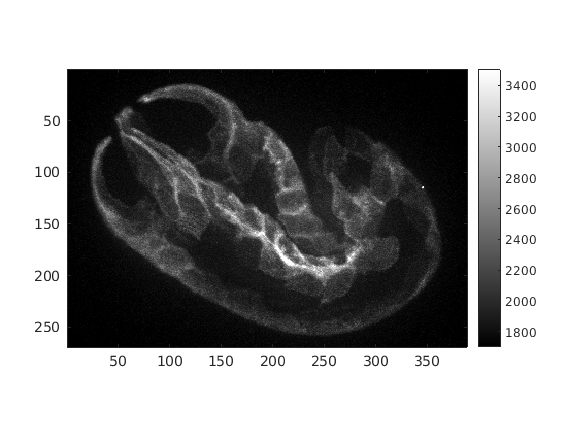

%How can we see the whole image all at once? The simplest way to do this is
%what's called a max projection. In a max projection for each row and
%column, we display only the maximum intensity across all slices in 3D. We
%can use the "dim" input to the max function to calculate the 2D maximum
%image across the 3D matrix like this:
max_proj = max(img,[],3);
figure
imagesc(max_proj,[1700,3500])
colormap gray
axis image
colorbar

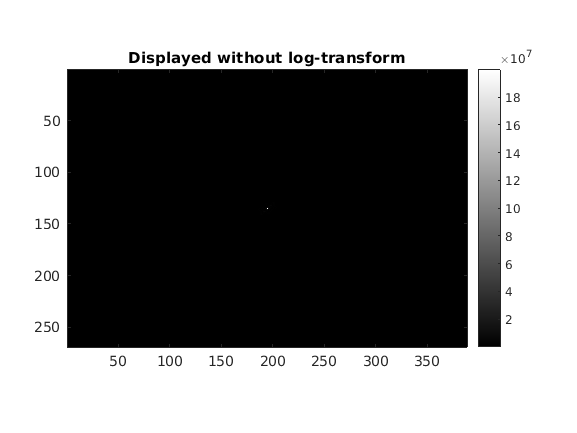

%In this lab we will consider the 2D max_proj image as our "original image",
%and compute 2D fast Fourier transform of it.
ft = fft2(max_proj);
ft_shift = fftshift(ft); % for better visualization, shift 0-frequency component to the center

figure
imagesc(abs(ft_shift)) % let's see what happens if we display its original value,
% complex number go away using abs(), use max projection 
% bright dot in the middle, zero axis doesn't represent any frequency,
% represents overall brightness of the image
colormap gray
axis image
colorbar
title("Displayed without log-transform")

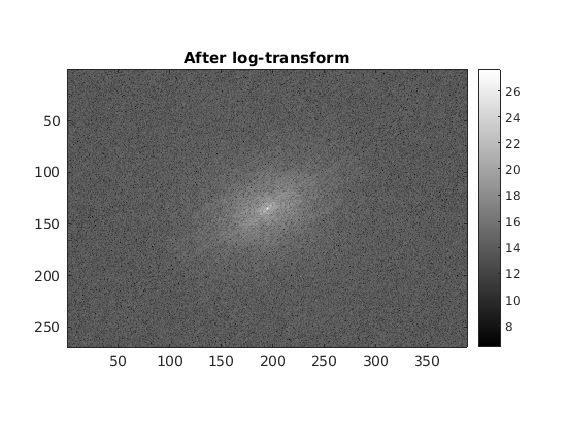


%% The reason why we need log-transform:
%% The 0-freqency component (central pixel) has a very large value compared to other regions
% center_x =  uint16((info(1).Height+1)/2);
% center_y =  uint16((info(1).Width +1)/2); % compute the coordinate of the center
% abs(ft_shift(center_x,center_y)) % value at the center
% abs(ft_shift(100,100)) % value at another location, much smaller
% sum(max_proj,'all') % center = summation of all pixel values of the image

% for better visualization of the small values especially around the high
% freqency regions, we can apply a log-transform

% bring down high intensity, bring up low intensity. Add 1 to avoid log(0), it's a small number 
figure
imagesc(log2(1+abs(ft_shift))) 
colormap gray
axis image
colorbar
title("After log-transform")

% remove low frequency components
% middle portion is low frequency
ft_1 = ft_shift; % copy the ft result to another variable
center_x =  uint16((info(1).Height+1)/2) 

center_x = uint16
135

center_y =  uint16((info(1).Width +1)/2) % compute the coordinate of the center

center_y = uint16
195

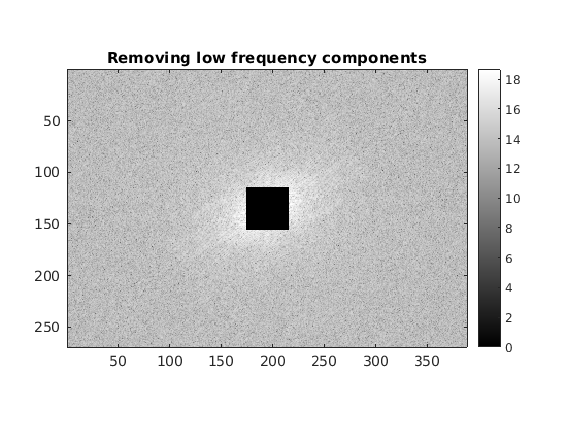

ft_1(center_x-20:center_x+20, center_y-20:center_y+20) = 0; % set the central region to 0

%box size to be 20, make adjustments for specific image, removing continous
%region 

% If you have questions on the MATLAB indexing, these documents are highly recommended:
% https://www.mathworks.com/help/matlab/math/array-indexing.html
% https://www.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html

figure
imagesc(log2(1+abs(ft_1)))
colormap gray
axis image
colorbar
title("Removing low frequency components")

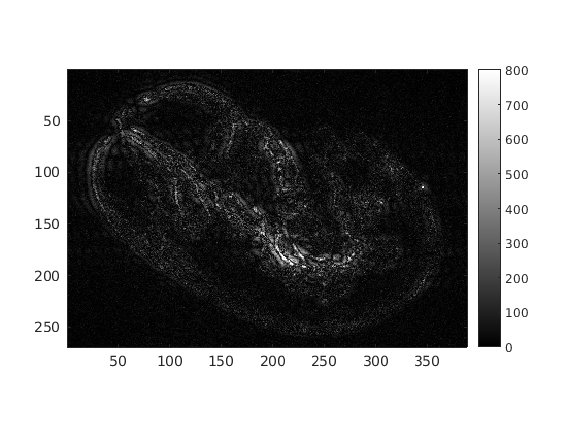


% inverse Fourier tranform, ifft2 is inverse fourier transform
% ifftshift lets us know about the format 
img_1 = ifft2(ifftshift(ft_1)); %shift it back to original and then inverse
imagesc(abs(img_1),[0,800]) % change the thresholds for the best visualization of your own image
colormap gray
axis image
colorbar

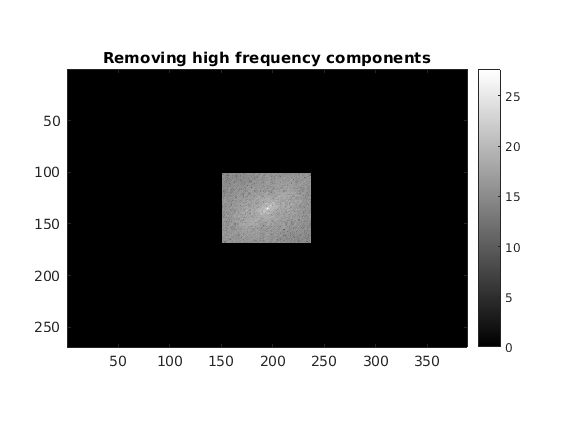

% remove high frequency components
ft_2 = ft_shift; % copy the ft result to another variable

ft_2(1:100, :) = 0; % set the first 100 rows to 0
ft_2(end-100:end, :) = 0; % set the last 100 rows to 0
ft_2(:, 1:150) = 0; % set the first 150 columns to 0
ft_2(:, end-150:end) = 0; % set the last 150 columns to 0

%set fourier domain to convert 0 of peripheral regions, set boundaries


figure
imagesc(log2(1+abs(ft_2)))
colormap gray
axis image
colorbar
title("Removing high frequency components")

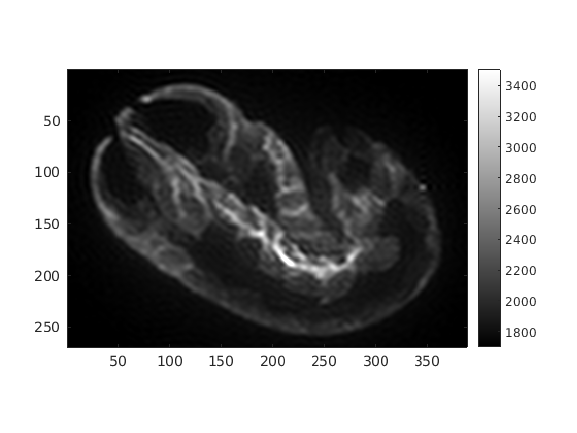


% inverse Fourier tranform
img_2 = ifft2(ifftshift(ft_2));
imagesc(abs(img_2),[1700,3500]) % change the thresholds for the best visualization of your own image
colormap gray
axis image
colorbar